# 多値出力モデルの例(作図用)

clear;clc;close all;
rng(1);
m=4;    %勝点のパターン数
N=600;  %各勝ち点のデータ数

rateDiff=[];    %レーティング差
q=[];   %結果の変数

for n1=1:m
    rateDiff=[rateDiff;randn(N,1)+n1];
    q=[q;n1*ones(N,1)];
end

[min(rateDiff) max(rateDiff)]

ans =    -2.0652    7.4562



edges=-2:0.25:7;
hCounts=[];
for n1=1:m
    ind = q==n1;
    hCounts=[hCounts;
        histcounts(rateDiff(ind),edges)];
end
hCounts

hCounts =      0     2     3     7    12    15    24    33    38    47    57    49    72    57    55    39    25    26    15     9     5     3     1     2     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     4     4     8    12    15    22    30    27    65    44    70    57    61    51    35    30    24    13     9     7     5     2     2     2     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     2     1     2     8     5     6    11    25    31    39    46    57    41    57    63    45    38    29    30    29    17     8     4     6     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     3     1     3     3    13    17    25    33    36    55    47    69    67    60    43    45    29    20    10     5     7     5     1     1


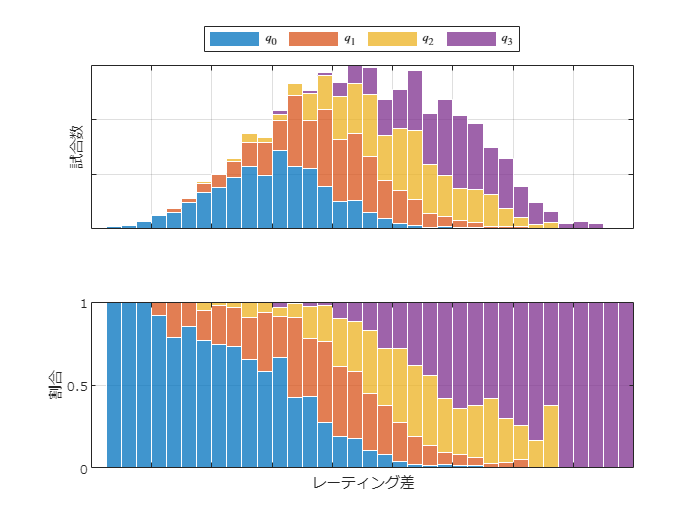


figure
tiledlayout(2,1);
nexttile;
bins=movmean(edges,2,'omitmissing','Endpoints','discard');
bar(bins, hCounts,'stacked','EdgeColor','w','FaceAlpha',0.75, ...
    'BarWidth',1   );
grid on;
set(gca,'fontname','メイリオ');
% xlabel('レーティング差');
xticklabels([]);
ylabel('試合数');yticklabels([]);
legend({'$q_0$','$q_1$','$q_2$','$q_3$'},'Interpreter','latex', ...
    'Location','northoutside','Orientation','horizontal');
xlim([min(edges) max(edges)]);
nexttile

bar(bins,hCounts./sum(hCounts),'stacked','EdgeColor','w','FaceAlpha',0.75, ...
    'BarWidth',1   );
grid on;
set(gca,'fontname','メイリオ');
xlabel('レーティング差');
xticklabels([]);
ylabel('割合');
xlim([min(edges) max(edges)]);

exportgraphics(gcf,'fig_multiOutSample_data.pdf');


for n1=1:m
    ind = q<=n1;
    mdl(n1,:)=glmfit(rateDiff,ind,'binomial','link','logit');
end

mdl

mdl =     1.6790   -1.4323
    4.0117   -1.5942
    5.1378   -1.3166
  102.5661    0.0000


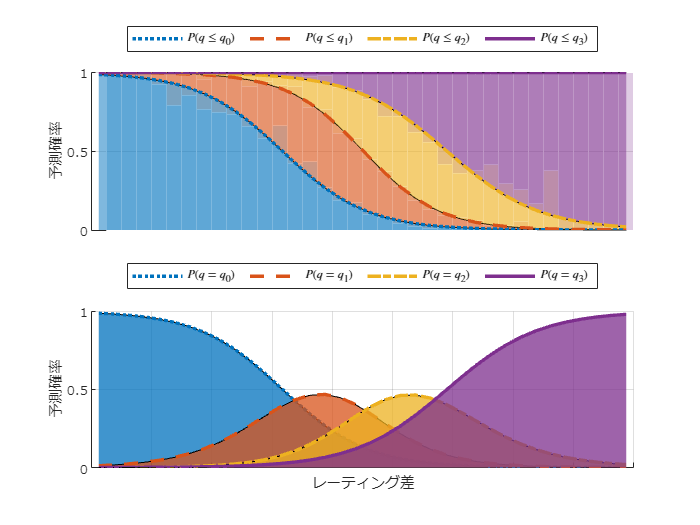


figure
tiledlayout(2,1);
nexttile;
hold on;
lineStyleStr={':','--','-.','-'};
areaData=[];
for n1=1:m
    if n1==1
        plotY=glmval(mdl(n1,:)',bins,"logit");
    else
        plotY=glmval(mdl(n1,:)',bins,"logit") ...
            -glmval(mdl(n1-1,:)',bins,"logit");
    end
    areaData=[areaData;plotY'];
end
bar(bins,hCounts./sum(hCounts),'stacked','EdgeColor','w','FaceAlpha',0.25, ...
    'BarWidth',1   );
set(gca,'ColorOrderIndex',1);
area(bins',areaData','FaceAlpha',0.5)
set(gca,'colororderindex',1)

for n1=1:m
    h(n1)=plot(bins, glmval(mdl(n1,:)',bins,"logit"),'LineWidth',2, ...
        LineStyle=lineStyleStr{n1});
end
grid on;
set(gca,'fontname','メイリオ');


xticklabels([]);
% xlabel('レーティング差');
ylabel('予測確率');
legend(h,{'$P(q\leq q_0)$', ...
    '$P(q\leq q_1)$', ...
    '$P(q\leq q_2)$', ...
    '$P(q\leq q_3)$'},'Interpreter','latex', ...
    'Location','northoutside','Orientation','horizontal');
xlim([min(edges) max(edges)]);
% exportgraphics(gcf,'fig_multiOutSample_glm.pdf');

% figure
nexttile;
hold on;
for n1=1:m
    if n1==1
        plotY=glmval(mdl(n1,:)',bins,"logit");
    else
        plotY=glmval(mdl(n1,:)',bins,"logit") ...
            -glmval(mdl(n1-1,:)',bins,"logit");
    end
    set(gca,'colororderindex',n1);
    area(bins, plotY,'FaceAlpha',0.75);
    set(gca,'colororderindex',n1);
    h(n1)=plot(bins, plotY,'LineWidth',2, ...
        LineStyle=lineStyleStr{n1});
end
grid on;
set(gca,'fontname','メイリオ');
xticklabels([]);
xlabel('レーティング差');
ylabel('予測確率');
legend(h,{'$P(q= q_0)$', ...
    '$P(q= q_1)$', ...
    '$P(q= q_2)$', ...
    '$P(q= q_3)$'},'Interpreter','latex', ...
    'Location','northoutside','Orientation','horizontal');
xlim([min(edges) max(edges)]);

exportgraphics(gcf,'fig_multiOutSample_glm.pdf');